# Correlation Electricity and GDP

Description: This algorithm calculates and plot the correlations of electricity generation and GDP growth. 

Developed by Natanael Bolson

Supervised by Prof. Tad Patzek

Energy Geosystems Group -ANPERC - KAUST 11/2020

clc
clear
close all

## Load Data

load Data_EIA.mat

% Electricity installed capacity (million kW)
El_Cap_Tot=Data_EIA.El_Cap_Tot(1,:);%[GW]
% nuclear electricity installed capacity (million kW)
El_Cap_Nuc=Data_EIA.El_Cap_Nuc(1,:);%[GW]
% fossil fuels electricity installed capacity (million kW)
El_Cap_Fos=Data_EIA.El_Cap_Fos(1,:);%[GW]
% renewable electricity installed capacity (million kW)
El_Cap_Ren=Data_EIA.El_Cap_Ren(1,:);%[GW]

% fossil fuels electricity net generation (billion kWh)
El_Gen_Fos=Data_EIA.El_Gen_Fos(1,:);%[TWh]
% electricity net generation (billion kWh)
El_Gen_Tot=Data_EIA.El_Gen_Tot(1,:);%[TWh]
El_Gen_G=diff(El_Gen_Tot)./El_Gen_Tot(1:end-1)*100;
Y_E=1981:2017;

% IMF 2020
% https://www.imf.org/external/datamapper/NGDP_RPCH@WEO/WEOWORLD
% Real GDP growth (Annual percent change)	
Y_G=1980:2025;													
World=[2.1	1.9	0.5	2.7	4.5	3.6	3.7	3.9	4.7	3.8	3.5	2.7	2.3	2.1	3.3	...
    3.3	3.9	4	2.6	3.5	4.8	2.5	3	4.3	5.4	4.9	5.5	5.5	3	-0.1	...
    5.4	4.3	3.5	3.5	3.5	3.4	3.3	3.8	3.5	2.8	-4.4	5.2	4.2	3.8	3.6	3.5];
% Forecast IMF 2010:2015 made in April 2010 WEO
GDP_For=[4.217	4.34	4.461	4.531	4.577	4.586];

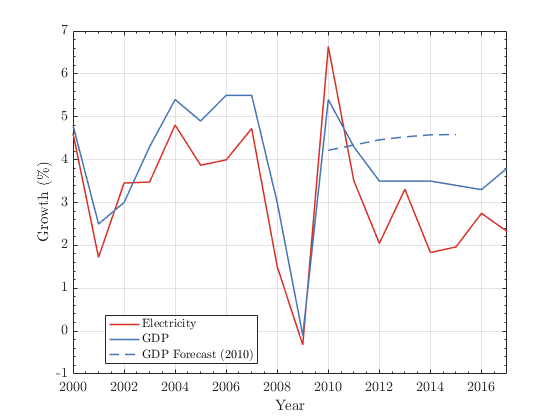

figure
plot(Y_E,El_Gen_G,'Color',[215,48,39]/255,'LineWidth',1.5)
hold on
plot(Y_G,World,'Color',[69,117,180]/255,'LineWidth',1.5)
plot(2010:2015,GDP_For,'--','Color',[69,117,180]/255,'LineWidth',1.5)

leg={'$\mathrm{Electricity}$','$\mathrm{GDP}$','$\mathrm{GDP~Forecast~(2010)}$'};
legend(leg,'Location','best','FontSize', 12,'NumColumns',1,...
    'interpreter','latex')
xlim([2000 2017])
xlabel('$$\mathrm{Year}$$','interpreter','latex')
ylabel('$$\mathrm{Growth~(\%)}$$','interpreter','latex')
box on
grid on
set(gca,'XMinorTick','on','YMinorTick','on')
set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',0.13,...
     'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')
% print('-depsc2','-r400','El_GDP.eps');
print('-dpng','-r400','El_GDP.png');

A=World(21:end-8);
B=El_Gen_G(20:end);

% Linear fitting
[xData, yData] = prepareCurveData( A, B );
% Set up fittype and options.
ft = fittype( 'poly1' );
opts = fitoptions( 'Method', 'LinearLeastSquares' );
opts.Robust = 'Bisquare';
% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft, opts );

% Fitted values to plot
F=0.9398*A-0.5375;

% Correlation coefficient
C=corrcoef(El_Gen_G(20:end),World(21:end-8))

C =     1.0000    0.8775
    0.8775    1.0000


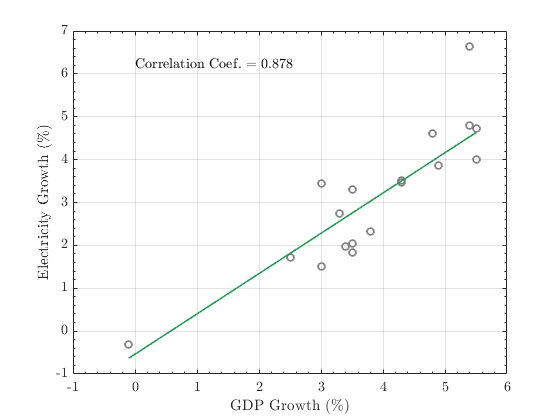

figure
scatter(World(21:end-8),El_Gen_G(20:end),50,[.5 .5 .5],'LineWidth',1.75)
hold on
plot(A,F,'Color',[26,152,80]/255,'LineWidth',1.5)
xlabel('$$\mathrm{GDP~Growth~(\%)}$$','interpreter','latex')
ylabel('$$\mathrm{Electricity~Growth~(\%)}$$','interpreter','latex')
text(0,6.2,'$$\mathrm{Correlation~ Coef.=0.878}$$','Fontsize',14,...
    'Interpreter','latex')
box on
grid on
set(gca,'XMinorTick','on','YMinorTick','on')
set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',0.13,...
     'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')
% print('-depsc2','-r400','El_GDP_Corr.eps');
print('-dpng','-r400','El_GDP_Corr.png');

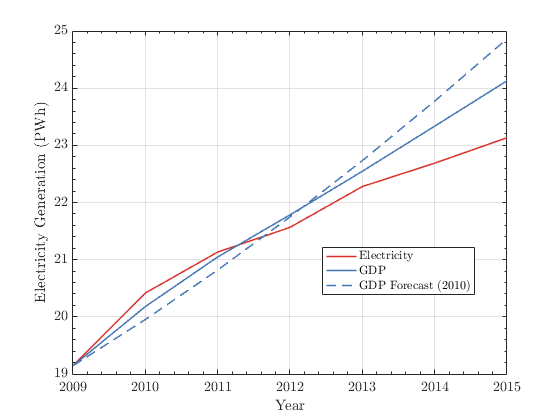

% Estimate electricity generation based on GDP data (Forecast and real)
El_2009=El_Gen_Tot(30);
El_F=El_2009;
El_G=El_2009;
for n=1:6
    El_For(n)=El_F+El_F*GDP_For(n)/100;
    El_GDP(n)=El_G+El_G*World(n+30)/100;
    
    El_F=El_For(n);
    El_G=El_GDP(n);    
end

Year=1980:2017;
Year(31:36);

figure
plot(Year(30:36),El_Gen_Tot(30:36)/1000,'Color',[215,48,39]/255,'LineWidth',1.5)
hold on
plot(Year(30:36),[El_2009 El_GDP]/1000,'Color',[69,117,180]/255,'LineWidth',1.5)
plot(Year(30:36),[El_2009 El_For]/1000,'--','Color',[69,117,180]/255,'LineWidth',1.5)
leg={'$\mathrm{Electricity}$','$\mathrm{GDP}$','$\mathrm{GDP~Forecast~(2010)}$'};
legend(leg,'Location','best','FontSize', 12,'NumColumns',1,...
    'interpreter','latex')
xlim([2009 2015])
xlabel('$$\mathrm{Year}$$','interpreter','latex')
ylabel('$$\mathrm{Electricity~Generation~(PWh)}$$','interpreter','latex')
box on
grid on
set(gca,'XMinorTick','on','YMinorTick','on')
set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',0.13,...
     'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')

% print('-depsc2','-r400','El_GDP_Con.eps');

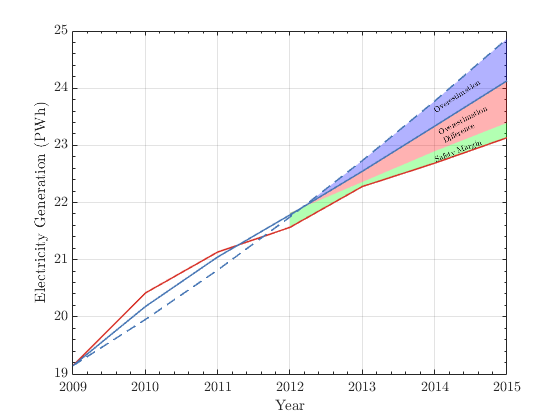

% Plot with area shaded
x2 = [Year(33:36), fliplr(Year(33:36))];
% Shaded area between overestimation and GDP
inBetween = [El_GDP(3:end), fliplr(El_For(3:end))];
% Shaded area mirrored
inBetween2 = [El_GDP(3:end), fliplr(El_GDP(3:end)-(El_For(3:end)-El_GDP(3:end)))];
% Shaded area difference real cf and shade overestimation
inBetween3 = [El_Gen_Tot(33:36), fliplr(El_GDP(3:end)-(El_For(3:end)-El_GDP(3:end)))];

figure
plot(Year(30:36),El_Gen_Tot(30:36)/1000,'Color',[215,48,39]/255,'LineWidth',1.5)
hold on
plot(Year(30:36),[El_2009 El_GDP]/1000,'Color',[69,117,180]/255,'LineWidth',1.5)
plot(Year(30:36),[El_2009 El_For]/1000,'--','Color',[69,117,180]/255,'LineWidth',1.5)
fill(x2, inBetween/1000,'b', 'edgecolor', 'none','facealpha',0.3);
fill(x2, inBetween2/1000,'r', 'edgecolor', 'none','facealpha',0.3);
fill(x2, inBetween3/1000,'g', 'edgecolor', 'none','facealpha',0.3);
plot(Year(30:36),El_Gen_Tot(30:36)/1000,'Color',[215,48,39]/255,'LineWidth',1.5)
hold on
plot(Year(30:36),[El_2009 El_GDP]/1000,'Color',[69,117,180]/255,'LineWidth',1.5)
plot(Year(30:36),[El_2009 El_For]/1000,'--','Color',[69,117,180]/255,'LineWidth',1.5)
text(2014,23.6,'Overestimation','Rotation',33,'Fontsize',8,'Interpreter','latex')
text(2014.1,23.125,{'Overestimation';'Difference'},'Rotation',28,'Fontsize',8,'Interpreter','latex')
text(2014,22.75,'Safety~Margin','Rotation',21,'Fontsize',8,'Interpreter','latex')
leg={'$\mathrm{Electricity}$','$\mathrm{GDP}$','$\mathrm{GDP~Forecast~(2010)}$'};
% legend(leg,'Location','best','FontSize', 12,'NumColumns',1,...
%     'interpreter','latex')
xlim([2009 2015])
xlabel('$$\mathrm{Year}$$','interpreter','latex')
ylabel('$$\mathrm{Electricity~Generation~(PWh)}$$','interpreter','latex')
box on
grid on
set(gca,'XMinorTick','on','YMinorTick','on')
set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',0.13,...
     'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')
%  print('-dpdf','-r400','El_GDP_Con.pdf');
print('-dpng','-r400','El_GDP_Con.png');

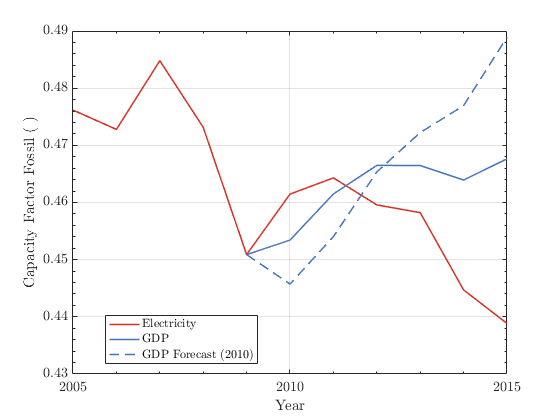

% Get Difference
El_Dif_For=El_For-El_Gen_Tot(31:36);%[TWh]
El_Dif_GDP=El_GDP-El_Gen_Tot(31:36);%[TWh]
% Capacity Factor based on real electricity generation
CF_Fos=(El_Gen_Fos(31:36)*1000)./(El_Cap_Fos(31:36)*8760);
% Capacity Factor based on GDP forecast
CF_Fos_For=CF_Fos+(El_Dif_For*1000)./(El_Cap_Fos(31:36)*8760);
% Capacity Factor based on real GDP
CF_Fos_GDP=CF_Fos+(El_Dif_GDP*1000)./(El_Cap_Fos(31:36)*8760);
% Capacity Factor based on real electricity generation (Full)
CF_Fos=(El_Gen_Fos(26:36)*1000)./(El_Cap_Fos(26:36)*8760);

figure
plot(Year(26:36),CF_Fos,'Color',[215,48,39]/255,'LineWidth',1.5)
hold on
plot(Year(30:36),[CF_Fos(5) CF_Fos_GDP],'Color',[69,117,180]/255,'LineWidth',1.5)
plot(Year(30:36),[CF_Fos(5) CF_Fos_For],'--','Color',[69,117,180]/255,...
    'LineWidth',1.5)
leg={'$\mathrm{Electricity}$','$\mathrm{GDP}$','$\mathrm{GDP~Forecast~(2010)}$'};
legend(leg,'Location','best','FontSize', 12,'NumColumns',1,...
    'interpreter','latex')
xlim([2005 2015])
xlabel('$$\mathrm{Year}$$','interpreter','latex')
ylabel('$$\mathrm{Capacity~Factor~Fossil~(~)}$$','interpreter','latex')
box on
grid on
set(gca,'XMinorTick','on','YMinorTick','on')
set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',0.13,...
     'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')

% print('-depsc2','-r400','El_GDP_CF.eps');

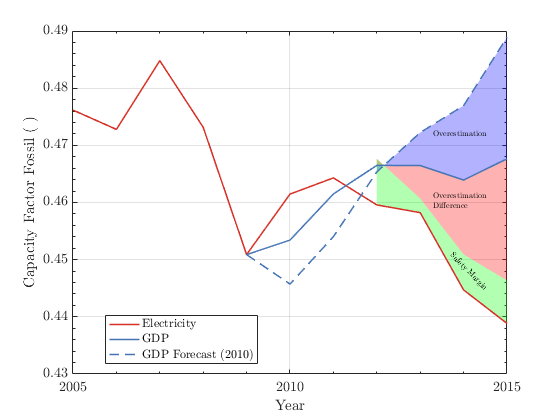

% Plot with area shaded
x2 = [Year(33:36), fliplr(Year(33:36))];
% Shaded area between overestimation and GDP
inBetween = [CF_Fos_GDP(3:end), fliplr(CF_Fos_For(3:end))];
% Shaded area mirrored
inBetween2 = [CF_Fos_GDP(3:end), fliplr(CF_Fos_GDP(3:end)-(CF_Fos_For(3:end)-CF_Fos_GDP(3:end)))];
% Shaded area difference real cf and shade overestimation
inBetween3 = [CF_Fos(8:end), fliplr(CF_Fos_GDP(3:end)-(CF_Fos_For(3:end)-CF_Fos_GDP(3:end)))];

figure
plot(Year(26:36),CF_Fos,'Color',[215,48,39]/255,'LineWidth',1.5)
hold on
plot(Year(30:36),[CF_Fos(5) CF_Fos_GDP],'Color',[69,117,180]/255,'LineWidth',1.5)
plot(Year(30:36),[CF_Fos(5) CF_Fos_For],'--','Color',[69,117,180]/255,...
    'LineWidth',1.5)
fill(x2, inBetween,'b', 'edgecolor', 'none','facealpha',0.3);
fill(x2, inBetween2,'r', 'edgecolor', 'none','facealpha',0.3);
fill(x2, inBetween3,'g', 'edgecolor', 'none','facealpha',0.3);
plot(Year(26:36),CF_Fos,'Color',[215,48,39]/255,'LineWidth',1.5)
hold on
plot(Year(30:36),[CF_Fos(5) CF_Fos_GDP],'Color',[69,117,180]/255,'LineWidth',1.5)
plot(Year(30:36),[CF_Fos(5) CF_Fos_For],'--','Color',[69,117,180]/255,...
    'LineWidth',1.5)
text(2013.3,0.472,'Overestimation','Rotation',0,'Fontsize',8,'Interpreter','latex')
text(2013.3,0.46,{'Overestimation';'Difference'},'Rotation',0,'Fontsize',8,'Interpreter','latex')
text(2013.7,0.451,'Safety~Margin','Rotation',-45,'Fontsize',8,'Interpreter','latex')
leg={'$\mathrm{Electricity}$','$\mathrm{GDP}$','$\mathrm{GDP~Forecast~(2010)}$'};
legend(leg,'Location','best','FontSize', 12,'NumColumns',1,...
    'interpreter','latex')
xlim([2005 2015])
xlabel('$$\mathrm{Year}$$','interpreter','latex')
ylabel('$$\mathrm{Capacity~Factor~Fossil~(~)}$$','interpreter','latex')
box on
grid on
set(gca,'XMinorTick','on','YMinorTick','on')
set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',0.13,...
     'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')
% print('-dpdf','-r400','El_GDP_CF.pdf');
print('-dpng','-r400','El_GDP_CF.png');

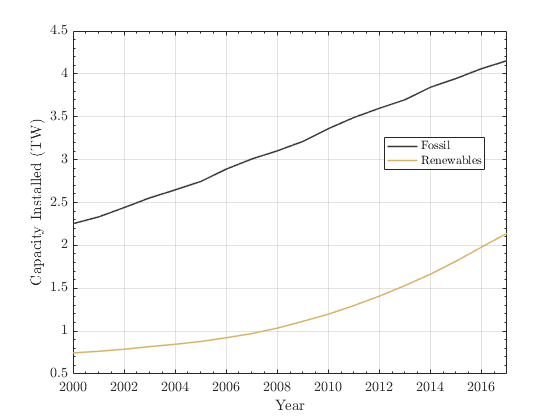

% Installed capacity of Fossil generation
figure
plot(Year,El_Cap_Fos/1000,'Color',[55,55,55]/255,'LineWidth',1.5)
hold on
plot(Year,El_Cap_Ren/1000,'Color',[216,179,101]/255,'LineWidth',1.5)
xlim([2000 2017])
xlabel('$$\mathrm{Year}$$','interpreter','latex')
ylabel('$$\mathrm{Capacity~Installed~(TW)}$$','interpreter','latex')
leg={'$$\mathrm{Fossil}$$';'$$\mathrm{Renewables}$$'};
legend(leg,'location','best','FontSize', 12,'NumColumns',1,'interpreter','latex')

box on
grid on
set(gca,'XMinorTick','on','YMinorTick','on')
set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',0.13,...
     'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')

%  print('-depsc2','-r400','Cap_Fos.eps');
